# Experimental Methods Midterm Dan Lawson

## Problem 1:

F = [21.4 19.2 18.6 22.4 19.8];
F_mean = mean(F)

F_std = std(F)


## Problem 3:

% Data
T = [260 270 280 290 300 310 320 330];
R = [1066 820 618 484 376 318 245 218];
R_log = log(R);
% Standard deviation of R
std_R = 15;

% Define weight
weights = 1./(std_R^2);

% Perform the weighted fit using polyfit
coefficients = polyfit(T, R_log, 1);
coefficients_weighted = polyfit(T, R_log, 1); % Weighted fit

% Evaluate the fitted polynomial
fit_R = polyval(coefficients, T);
fit_R_weighted = polyval(coefficients_weighted, T);

% Display the fit coefficients
disp(['a: ', num2str(coefficients_weighted(1))]);

a: -0.023091


disp(['b: ', num2str(coefficients_weighted(2))]);

b: 12.9201


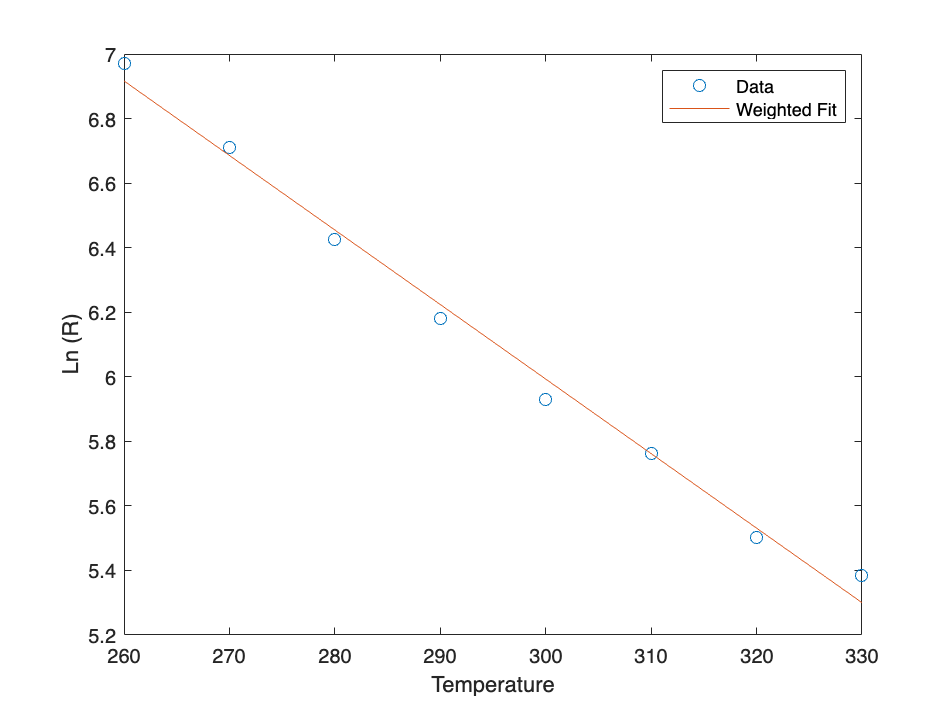

err_abs_a = 0.0000e+00 + 1.9493e+02i


% Plot the data and the fit
plot(T, R_log, 'o', 'DisplayName', 'Data');
hold on;
%plot(T, fit_R, 'DisplayName', 'Unweighted Fit');
plot(T, fit_R_weighted, 'DisplayName', 'Weighted Fit');
xlabel('Temperature');
ylabel('Ln (R)');
legend;
hold off